Data Science (Prof. Neff)                    Abgabedatum 01.12.2020

Versuch Konfidenzintervalle - Aufgaben zur schließenden Statistik

Gruppe 6:    Benjamin Hamm (2060696), Jan Klotter (2060690),

                    Anna Kuhn (2051063), Michael Schulze (2061282)

# 1. Konfidenzintervalle

clear

## 1a) + 1b) Darstellen der Daten und Konfidenzintervalle Büroklammer


% Büroklammern
data_buero = readtable('Lebensdauer_Bueroklammer.csv')

data_buero = 75×1 table
    Zyklen
    ______

       9  
      61  
       3  
       2  
       4  
       7  
      25  
      16  
      97  
       4  
       5  
      50  
       2  
       2  
      13  
      17  



% Bueroklammern b)
mean_norm = mean(data_buero.Zyklen)

mean_norm = 15.6133

pd_norm_buero = fitdist(data_buero.Zyklen,'Normal')

pd_norm_buero =   NormalDistribution

  Normal distribution
       mu = 15.6133   [10.6343, 20.5924]
    sigma = 21.6407   [18.6461, 25.7903]


ci_normal=paramci(pd_norm_buero,'Alpha',0.05)

ci_normal =    10.6343   18.6461
   20.5924   25.7903



[h0,p,t_ci_buero,t_stats_buero] = ttest(data_buero.Zyklen)

h0 = 1

p = 2.3904e-08

t_ci_buero =    10.6343
   20.5924


t_stats_buero = struct with fields:
    tstat: 6.2482
       df: 74
       sd: 21.6407



pd_weibull_buero = fitdist(data_buero.Zyklen, 'Weibull')

pd_weibull_buero =   WeibullDistribution

  Weibull distribution
    A =  15.2792   [11.8995, 19.6187]
    B = 0.960767   [0.820185, 1.12545]


ci_weibull = paramci(pd_weibull_buero,'Alpha',0.05)

ci_weibull =    11.8995    0.8202
   19.6187    1.1254



pd = makedist('Weibull')

pd =   WeibullDistribution

  Weibull distribution
    A = 1
    B = 1


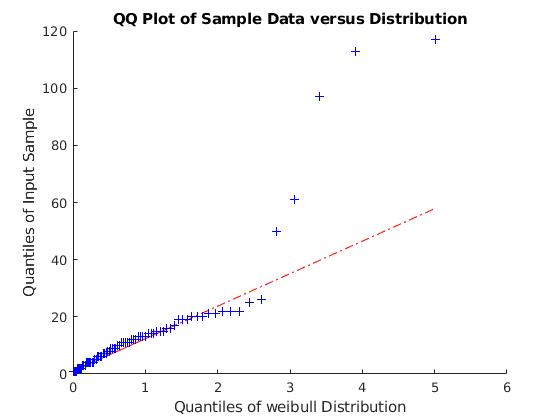

figure(1)
qqplot(data_buero.Zyklen,pd)

% bis 2,8 eindeutige Weibull-Verteilung, danach sind Outliner vorhanden.
% daher nehmen wir die Weibull-Verteilung als gute Näherung einer
% Verteilung an

[boot_buero, data_boot_buero]=bootstrp(10,@median,data_buero.Zyklen)

boot_buero =     10
     9
    11
    11
    10
     9
    11
    12
    12
    11


data_boot_buero =     33    54    38    23    46     1    45     5    72    74
     1    41    66    66    44    21    66     7    36    38
    17     6    57    62    73    50    56    44    54     4
    30    12    56    75     5    16    53     3    37     9
    55    52    64    29    54    52    65     8    28    36
    58    26    18    39    68     9    11    30    47    13
    19    64    26    57    15    34    10    41    50    35
     3    72    73    30    68    10    35    17    17    47
    72    57    11    70    62    39    22    29    42     9
    40     3     8    33    50    20    51    69    72     7



%x-Daten, Anzahl Datenwerte etc.
anzahl = length(data_buero.Zyklen)

anzahl = 75

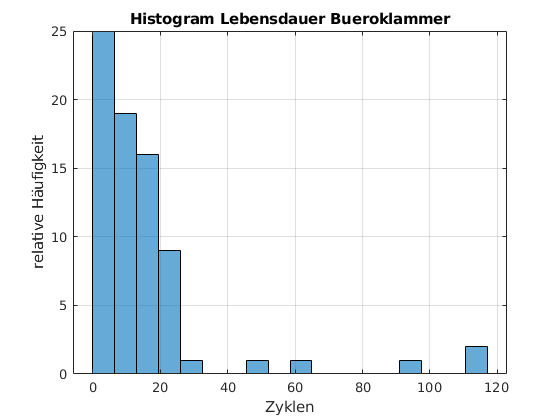

x = (min(data_buero.Zyklen)-2:0.1:max(data_buero.Zyklen)+2);

%histogram(data_buero.Zyklen)
figure(2)
histogram(data_buero.Zyklen,2*round(sqrt(anzahl)))
grid on
title('Histogram Lebensdauer Bueroklammer')
xlabel('Zyklen')
ylabel('relative Häufigkeit')

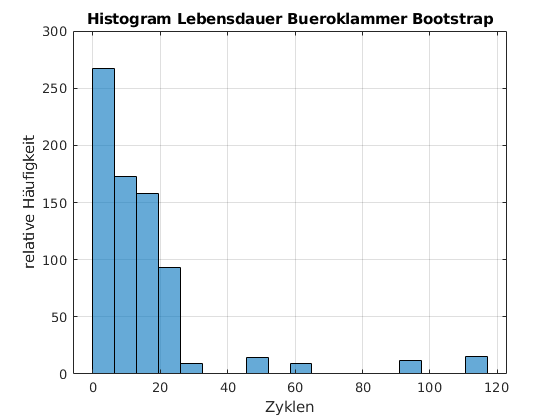



%histogram(data_buero.Zyklen(data_boot_buero),6)
figure(3)
histogram(data_buero.Zyklen(data_boot_buero),2*round(sqrt(anzahl)))
grid on
title('Histogram Lebensdauer Bueroklammer Bootstrap')
xlabel('Zyklen')
ylabel('relative Häufigkeit')



[ci,mean_intervall_bootstrap] = bootci(10,{@mean,data_buero.Zyklen},'Alpha',0.05)

ci =    13.2506
   16.6800


mean_intervall_bootstrap =    12.8933
   16.0267
   13.6000
   16.4267
   16.1200
   14.2000
   16.6800
   14.6533
   15.3600
   14.2267


% Bootstrap vergrößert künstlich die Stichprobe, daher ist das
% Konvidenzintervall kleiner als bei den anderen Verfahren,
% daher nehmen wir das Bootstrap-Verfahren ebenfalls als geeignet an

matrix = [mean_norm ci_normal(1) ci_normal(2);
    mean_norm t_ci_buero(1) t_ci_buero(2);
    mean_norm ci_weibull(1) ci_weibull(2);
    mean(mean_intervall_bootstrap) ci(1) ci(2)]

matrix =    15.6133   10.6343   20.5924
   15.6133   10.6343   20.5924
   15.6133   11.8995   19.6187
   15.0187   13.2506   16.6800


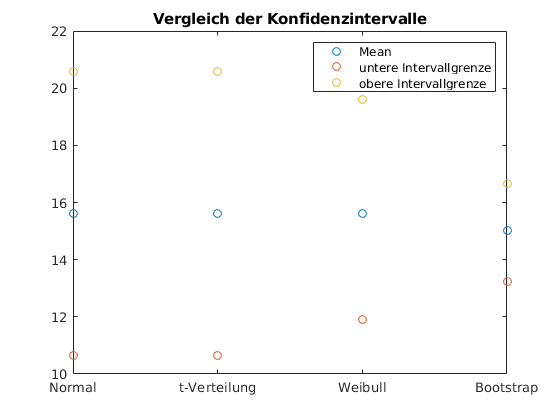


figure(4)
plot(matrix,'o')
title("Vergleich der Konfidenzintervalle")
legend( "Mean", "untere Intervallgrenze", "obere Intervallgrenze")
xlim([1 4])
xticks([1 2 3 4])
xticklabels({'Normal', 't-Verteilung', 'Weibull', 'Bootstrap'})

## 1c) Diskussion Verfahren Büroklammer


% Bootstrap und Weibull eignen sich am besten, da die Konvidenzintervall am
% kleinsten sind (im Gegensatz zur Normal- und t-Verteilung).
% Der qqPlot der Weibull ist annähernd linear bis 2,8

## 1a) + 1b) Darstellen der Daten und Konfidenzintervalle MSA1 Versuch


% Wasser MSA1 b)
data_msa = readtable('MSA_Verfahren1_200ml_Jan.csv')

data_msa = 25×1 table
    Gewicht_in_g
    ____________

        199     
        213     
        185     
        198     
        205     
        191     
        184     
        193     
        199     
        206     
        207     
        210     
        213     
        197     
        205     
        203     



mean_norm = mean(data_msa.Gewicht_in_g)

mean_norm = 200.0400


pd = makedist('Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 0
    sigma = 1


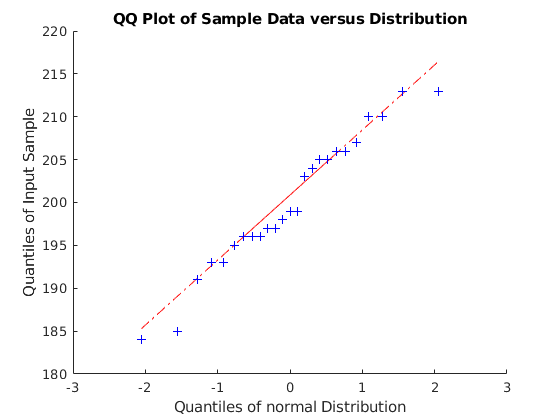


figure(5)
qqplot(data_msa.Gewicht_in_g,pd)

% qqPlot der Normalverteilung nähert sich den Daten am genausten an

pd_norm_msa = fitdist(data_msa.Gewicht_in_g, 'Normal')

pd_norm_msa =   NormalDistribution

  Normal distribution
       mu =  200.04   [196.787, 203.293]
    sigma = 7.88184   [6.15436, 10.9648]


ci_normal_msa = paramci(pd_norm_msa, 'Alpha', 0.05)

ci_normal_msa =   196.7865    6.1544
  203.2935   10.9648



[~,~,t_ci_msa,t_stats_msa] = ttest(data_msa.Gewicht_in_g)

t_ci_msa =   196.7865
  203.2935


t_stats_msa = struct with fields:
    tstat: 126.8994
       df: 24
       sd: 7.8818



pd_weibull_msa = fitdist(data_msa.Gewicht_in_g,'Weibull')

pd_weibull_msa =   WeibullDistribution

  Weibull distribution
    A =  203.71   [200.821, 206.64]
    B = 29.0413   [21.4884, 39.2491]


ci_weibull_msa = paramci(pd_weibull_msa, 'Alpha', 0.05)

ci_weibull_msa =   200.8207   21.4884
  206.6400   39.2491



[boot_msa, data_boot_msa]=bootstrp(10,@median,data_msa.Gewicht_in_g)

boot_msa =    199
   205
   196
   204
   199
   196
   199
   199
   198
   197


data_boot_msa =     13    13    13    15     5    24    20    17    25    24
    18    18    24     5    20     8    19    10     4    24
     4    12    17    25     2    25    25     1    10     9
    12     5    18    16     3    23    20     3     1    24
     5    24    24    20    11    21    23    25    13    16
    11     1    25    15     1    17     9     7    16    17
    15    15    11    18     5    21    21     2     4    16
    22    25    20    21    25     2    25    19     3     2
    23     5    12     6    14    15     6     9    24    17
     4    13    17     7    23    25    11    20    23    25


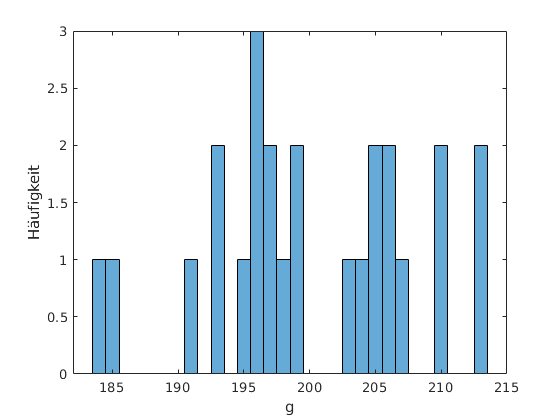


figure(6)
histogram(data_msa.Gewicht_in_g)
xlabel("g")
ylabel("Häufigkeit")

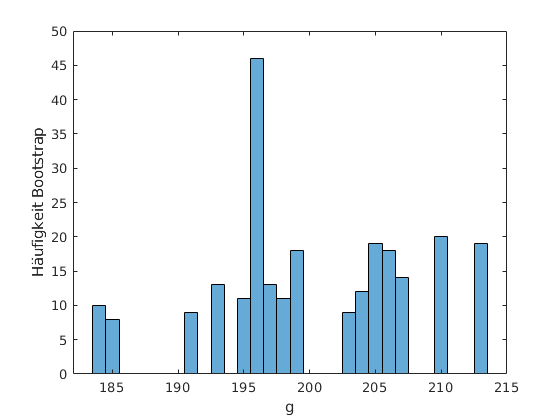


figure(7)
histogram(data_msa.Gewicht_in_g(data_boot_msa))
xlabel("g")
ylabel("Häufigkeit Bootstrap")


[ci,mean_intervall_bootstrap] = bootci(10,{@mean,data_msa.Gewicht_in_g},'Alpha',0.05)

ci =   197.1600
  201.1171


mean_intervall_bootstrap =   200.3600
  197.1600
  200.4800
  197.9200
  199.5200
  202.0000
  200.3600
  201.2400
  200.8800
  200.1600


pd = makedist('Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 0
    sigma = 1


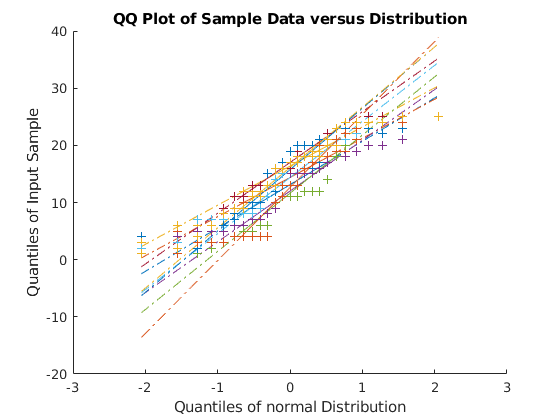


figure(8)
qqplot(data_boot_msa,pd)


matrix = [mean_norm ci_normal_msa(1) ci_normal_msa(2);
    mean_norm t_ci_msa(1) t_ci_msa(2);
    mean_norm ci_weibull_msa(1) ci_weibull_msa(2);
    mean(mean_intervall_bootstrap) ci(1) ci(2)]

matrix =   200.0400  196.7865  203.2935
  200.0400  196.7865  203.2935
  200.0400  200.8207  206.6400
  200.0080  197.1600  201.1171


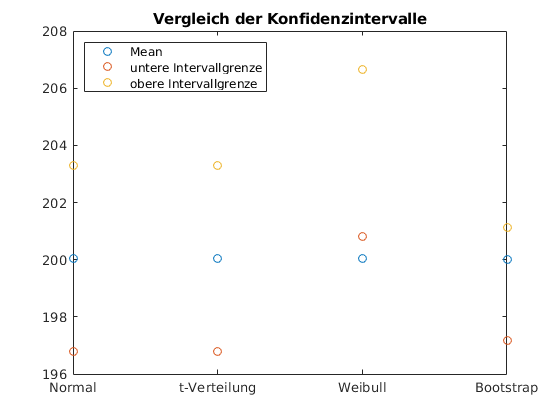


figure(9)
plot(matrix,'o')
title("Vergleich der Konfidenzintervalle")
legend( "Mean", "untere Intervallgrenze", "obere Intervallgrenze", 'Location',...
    'northwest')
xlim([1 4])
xticks([1 2 3 4])
xticklabels({'Normal', 't-Verteilung', 'Weibull', 'Bootstrap'})

## 1c) Diskussion Verfahren MSA1 Versuch


% Die Normal und t-Verteilung zeigen gute Näherungen für die Daten.
% Das Bootstrap Verfahren hat jedoch ein kleineres Konfidenzintervall und
% ist somit noch besser geeignet als die anderen beiden.
% Weibull kann nicht angewandt werden, der Mittelwert liegt sogar außerhalb
% des Konfidenzintervalls

# 2. Hypothesentests

## 2a) Darstellen der Daten und Nullhypothese


% H0 = Medikament hat keine Auswirkung auf Cholesterinspiegel
% H1 = Medikament beeinflusst den Cholesterinspiegel

%Messwerte einlesen
data_cholesterin_senker = readtable('cholesterinsenker.csv')

data_cholesterin_senker = 10×2 table
     A      B 
    ___    ___

      0    -22
    -27    -14
    -16    -15
    -13    -32
     -6    -22
    -27    -34
     -5    -38
    -22    -16
     -9    -25
     -3    -26


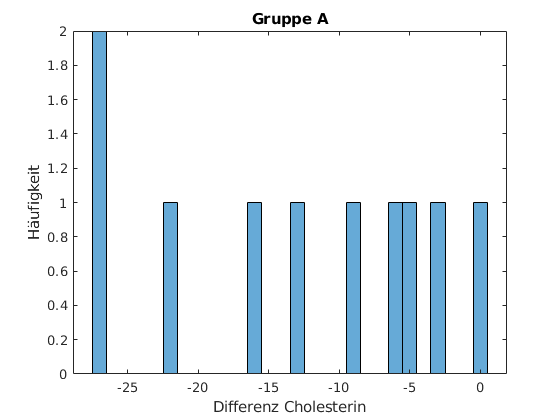


figure(10)
histogram(data_cholesterin_senker.A)
title("Gruppe A")
xlabel("Differenz Cholesterin")
ylabel("Häufigkeit")

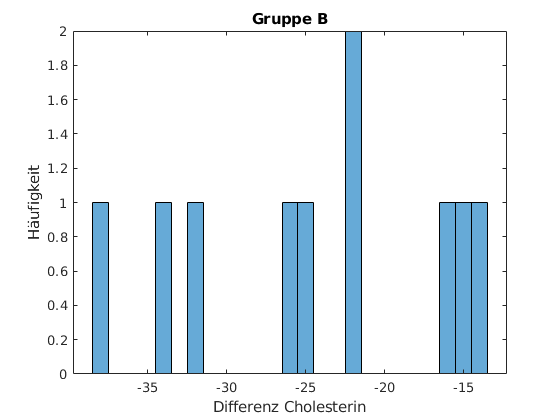


figure(11)
histogram(data_cholesterin_senker.B)
title("Gruppe B")
xlabel("Differenz Cholesterin")
ylabel("Häufigkeit")


% statistische Größen
mediana = median(data_cholesterin_senker.A)

mediana = -11

medianb = median(data_cholesterin_senker.B)

medianb = -23.5000

meana = mean(data_cholesterin_senker.A)

meana = -12.8000

meanb = mean(data_cholesterin_senker.B)

meanb = -24.4000

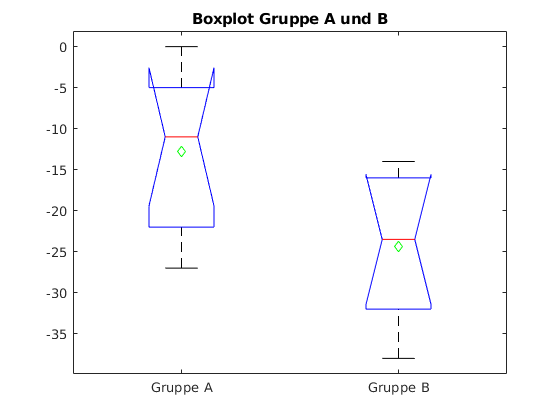


figure(12)
boxplot([data_cholesterin_senker.A,data_cholesterin_senker.B],...
    "Notch","on","Labels",{'Gruppe A', 'Gruppe B'})
hold on
plot([mean(data_cholesterin_senker.A),mean(data_cholesterin_senker.B)], 'dg')
title("Boxplot Gruppe A und B")
hold off

## 2b) Test unter Annahme Grundgesamtheit normalverteilt


% t-Test
[h0_ttest,p_ttest,ci_ttest,stats_ttest]=...

h0_ttest = 0

p_ttest = 0.0107

ci_ttest =    -0.1355
   23.3355


stats_ttest = struct with fields:
    tstat: 2.8452
       df: 18
       sd: 9.1165


    ttest2(data_cholesterin_senker.A,data_cholesterin_senker.B, 'alpha',0.01)


## 2c) Test unter Annahme Grundgesamtheit nicht normalverteilt


% Verteilungsfreien Test auf Median (Mann-Whitney Test):
[p_rank,h0_rank,stats_rank]=...

p_rank = 0.0280

h0_rank = logical
   0


stats_rank = struct with fields:
       zval: 2.1972
    ranksum: 134.5000


    ranksum(data_cholesterin_senker.A,data_cholesterin_senker.B, 'alpha',0.01)


## 2d) Vergleich beider Tests


% Wir nehmen für beide Fälle die Nullhypothese H0 an, da h0=0 ist und p größer 
% als alpha ist. Beim t-Test wird als Lagemaß der Mean verwendet und im 
% Mann-Whitney-Test der Median. Da der Median und der Mean fast gleich sind,
% kann die Aussage getroffen werden, dass die Stichproben aus einer 
% symmetrischen Verteilung stammen.
% % tstat liegt bei 2.8452 und zval bei 2.1972 und sind somit kleiner als
% t_kritisch 2.878 (zweiseitiger Test), welches ein weiteres Argument für 
% die Annahme der h0 ist.
% Da zval kleiner als tstat ist, liefert der Mann-Whitney Test ein sicheres
% Ergebnis.

## 2e) Annahme auf Normalverteilung der Stichprobe gerechtfertigt?

### qq-Plot auf Normalverteilung

pd = makedist('Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 0
    sigma = 1


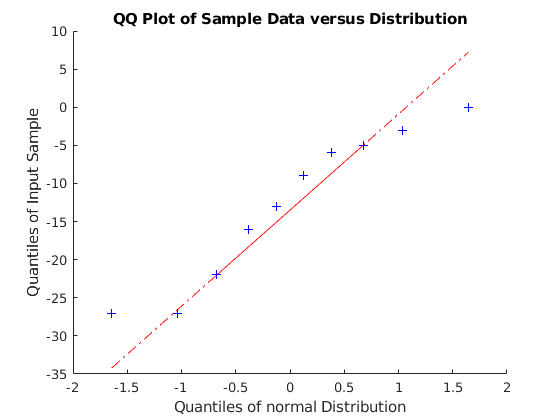


figure(13)
qqplot(data_cholesterin_senker.A,pd)

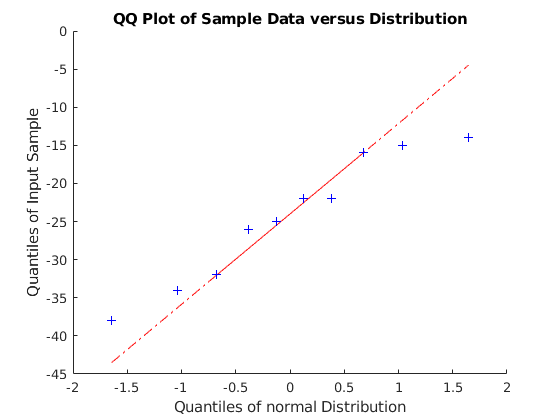


figure(14)
qqplot(data_cholesterin_senker.B,pd)

% Anhand des qq-Plotes kann die Annahme getroffen werden, dass die Stichproben
% aus einer Normalverteilung stammt.


### Anderson Darling Test


% H0 = Die Daten stammen aus einer Normalverteilung
% (h0 = 1 heißt, dass die Daten nicht normalverteilt sind)
[h0_adA, p_adA, ci_adA, stats_adA] = adtest(data_cholesterin_senker.A,'Alpha',0.01)

h0_adA = logical
   0


p_adA = 0.4677

ci_adA = 0.3289

stats_adA = 0.9339

[h0_adB, p_adB, ci_adB, stats_adB] = adtest(data_cholesterin_senker.B,'Alpha',0.01)

h0_adB = logical
   0


p_adB = 0.6616

ci_adB = 0.2635

stats_adB = 0.9339

% Nullhypothese wird beibehalten, da h0 in beiden Fällen 0 ist und die p-Werte
% in beiden Fällen, größer als alpha sind. Somit kann eine Normalverteilung der
% Daten angenommen werden.


## 2f) Schlussfolgerungen

% Der t-Test und der Mann-Whitney-Test lieferte das Ergebnis, dass es keinen 
% Zusammenhang zwischen dem Medikament und dem Cholesterin-Wert gibt.
% Als medizinische Laien erkennen wir den Zusammenhang, dass die Gruppe B 
% einen größeren Cholesterinwertrückgang hat als Gruppe A.
% Daher würden wir eine weitere Studie mit einer größeren Stichprobe durchführen.
% Jedoch wissen wir nicht, in welchem Spektrum sich eine Cholesterinsenkung
% befinden muss, damit das Medikament als wirksam bezeichnet werden kann.
